# Predicting Fuel Economy

In this demo, we use regression trees to predict the fuel economy of vehicles. 

## Loading Excel file representing Fuel Economy Data

CarData = importCarTable('.\dataXLS\2004dat.xlsx');

## Categorical Variables

Many of the variables represent discrete items, or categories: a car or a truck, front wheel or rear wheel drive, etc. To conserve memory and accurately classify these, we'll convert them to `categorical` variables.

CarData.Car_Truck = categorical(CarData.Car_Truck);
CarData.Police = categorical(CarData.Police);
CarData.Transmission = categorical(CarData.Transmission);
CarData.Drive = categorical(CarData.Drive);
CarData.AC = categorical(CarData.AC);
CarData.City_Highway = categorical(CarData.City_Highway);

% Not enough samples of each Manufacturer and Car Line (100s unique ones)
% Year is all the same
CarData.MfrName = [];
CarData.CarLine = [];
CarData.Year = [];

% %%  Test with 10% of the Data
% % Several of the techniques below use random numbers.  We are going
% % to set the random number generator here to ensure repeatability.
% rng(5)

## Partition Data for Cross Validation

cvpartition helps us create a cross-validation partition for data. We create a test set (10% of data) and training set (90% of data).

% Build cross-validation partition
c = cvpartition(height(CarData),'holdout');

% Extract data at indices
mdlTrain = CarData(training(c),:);
mdlTest  = CarData(test(c),:);

% Extract predictors and response
X = CarData;
X.MPG = []; % Remove mpg
Y = CarData.MPG;

## Multiple Linear Regression

First try multiple linear regression

% Fit linear model
modelLR = fitlm(mdlTrain,'ResponseVar', 'MPG');
disp(modelLR)

Linear regression model:
    MPG ~ [Linear formula with 19 terms in 18 predictors]

Estimated Coefficients:
                             Estimate         SE          tStat         pValue   
                            __________    __________    __________    ___________
    (Intercept)                 43.858        1.7825        24.605    4.4781e-117
    Car_Truck_truck            -1.4722       0.22811       -6.4539     1.3625e-10
    EngDisp                  -0.020771     0.0031289       -6.6385     4.0654e-11
    Police_Y                   -1.5635        1.3739        -1.138        0.25526
    RatedHP                  -0.010532     0.0021439       -4.9123     9.7278e-07
    Transmission_A5            0.27448         1.328       0.20668        0.8362


Test Data R^2: 0.854986


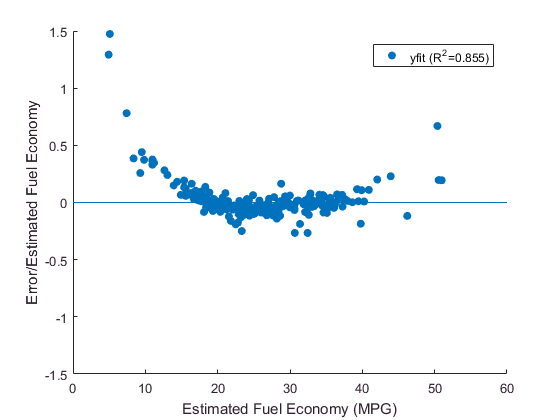

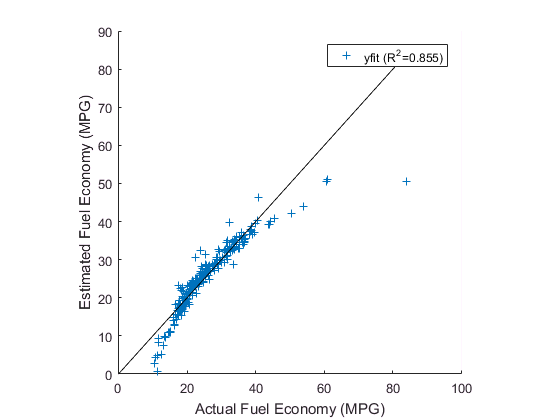


% Make prediction on test set
yfitLR = predict(modelLR,mdlTest);

% Show Results
showFit(mdlTest.MPG, yfitLR)

## Stepwise Linear Regression

Stepwise linear regression adds each term to see which ones decrease the error the most.

modelSW = stepwiselm(mdlTrain,'ResponseVar', 'MPG','Upper','linear');

1. Adding CO2, FStat = 9690.3664, pValue = 0
2. Adding Transmission, FStat = 8.9751, pValue = 2.2587e-19
3. Adding Drive, FStat = 32.2891, pValue = 1.57029e-14
4. Adding City_Highway, FStat = 111.4456, pValue = 2.132297e-25
5. Adding Weight, FStat = 150.642, pValue = 1.882935e-33
6. Adding Comp, FStat = 51.7411, pValue = 8.87876e-13
7. Adding EVSpeedRatio, FStat = 43.0015, pValue = 6.9254e-11
8. Adding EngDisp, FStat = 66.868, pValue = 5.07032e-16
9. Adding Car_Truck, FStat = 24.5178, pValue = 7.97417e-07
10. Adding FuelType, FStat = 33.3585, pValue = 8.85543e-09
11. Adding HC, FStat = 32.3019, pValue = 1.51181e-08
12. Adding AC, FStat = 20.4032, pValue = 6.63519e-06
13. Adding RatedHP, FStat = 30.104, pValue = 4.61075e-08
14. Adding PRP, FStat = 5.8856, pValue = 0.015353


disp(modelSW)

Linear regression model:
    MPG ~ [Linear formula with 15 terms in 14 predictors]

Estimated Coefficients:
                             Estimate         SE          tStat        pValue   
                            __________    __________    _________    ___________
    (Intercept)                 43.538        1.7672       24.638    2.2747e-117
    Car_Truck_truck            -1.4932       0.21873       -6.827      1.144e-11
    EngDisp                  -0.019836     0.0029373      -6.7531     1.8873e-11
    RatedHP                  -0.011134     0.0020109      -5.5367     3.4853e-08
    Transmission_A5             0.1672        1.3259      0.12611        0.89966
    Transmission_A6            0.84898        1.4586      0.58205         0.5606
    <s

disp(mdlTrain.Properties.VariableNames(modelSW.VariableInfo.InModel).');

    'Car_Truck'
    'EngDisp'
    'RatedHP'
    'Transmission'
    'Drive'
    'Weight'
    'Comp'
    'EVSpeedRatio'
    'AC'
    'PRP'
    'FuelType'
    'City_Highway'
    'HC'
    'CO2'



Test Data R^2: 0.855233


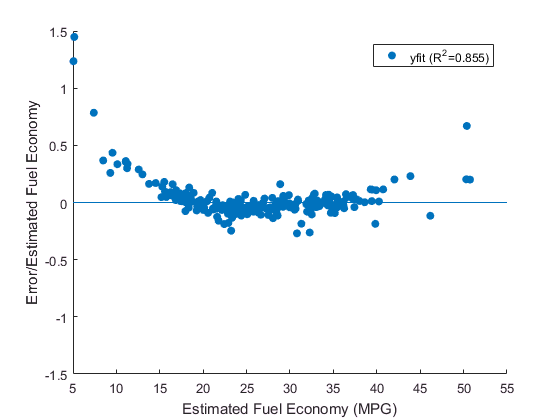

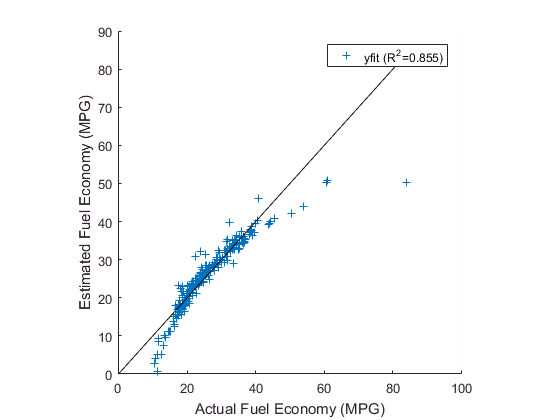


% Make prediction on test set
yfitSW  = predict(modelSW,mdlTest);

% Show Results
showFit(mdlTest.MPG, yfitSW)

## Support Vector Regression

modelsvm = fitrsvm(mdlTrain,'MPG');
disp(modelsvm)

% Make prediction on test set
yfitsvm  = predict(modelsvm,mdlTest);

% Show Results
showFit(mdlTest.MPG, yfitsvm)

## Regression Trees: Train the Tree

In many cases, the form of the relationship between predictors and a response is unknown. Decision trees offer a nonparametric alternative for regression.

t = fitrtree(mdlTrain,'MPG');
t2 = prune(t,'level',250);
view(t2); % textual
view(t2,'mode','graph'); % as a tree

## Regression Trees: Evaluate the Tree

yfitT = predict(t, mdlTest);

% Show Results
showFit(mdlTest.MPG, yfitT)

## Bagged Decision Trees

Bagging stands for bootstrap aggregation. Every tree in the ensemble is grown on an independently drawn sample of input data. To compute prediction for the ensemble of trees, fitensemble takes an average of predictions from individual trees. Ensemble techniques such as bagging combining many weak learners to produce a strong learner.

To use default values:

`tbfit = fitensemble(Xtrain,Ytrain,'Bag',100,'tree','type','regression');`

To determine how many trees to use in your ensemble:

`treeLoss = oobLoss(tbfit,'mode','cumulative')`

`plot(1:length(treeLoss),treeLoss)`

oobLoss (Out-of-bag regression error) computes MSE versus the number of grown trees. You can use a similar technique to figure out best mininum leaf size.

ttemp = templateTree('MinLeaf',1);
tbfit = fitensemble(mdlTrain,'MPG','Bag',100,ttemp,'type','regression');

% Predict
yfitTB = predict(tbfit,mdlTest);

% Show Results
showFit(mdlTest.MPG, yfitTB)

## Bagged Decision Trees: Predictor Importance

Predictor importance offers insight into the relative importance of each predictor in the model. It is calculated by summing changes in the mean squared error (MSE) due to splits on every predictor and dividing the sum by the number of branch nodes.

figure
pI = predictorImportance(tbfit);
barh(pI)
set(gca,'YTick',1:numel(X.Properties.VariableNames));
set(gca,'YTickLabel',X.Properties.VariableNames);
xlabel('Predictor Importance')

## Sequential Feature Selection

Sequential feature selection selects a subset of features from the data matrix X that best predict the data in Y by sequentially selecting features until there is no improvement in prediction. We are using 3 fold cross-validation so we can use the whole data set here without having to break up a training set and a test set. Normally, you may want to use a higher fold, but we are keeping it small for demo purposes. We can then see which features to keep in our model.

% Data needs to be numeric
Xdummy = dummytable(X);
XNumeric = table2array(Xdummy);

gcp; % open a pool of workers

opts = statset('display','iter','UseParallel','always','TolFun',1e-2);

% use our cv partition object with 3-fold cross validation
cv = cvpartition(height(X),'k',3);

% Determine important features
fs = sequentialfs(@featureTest,XNumeric,Y,'options',opts,'cv',cv);

% Display
disp(Xdummy.Properties.VariableNames(fs).')

## Treebagger with New Predictor Set

About the same answer but smaller set of predictors. Important for computational speed, avoiding overtraining, and for general simplicity. Could yield a more accurate result, as well.

ttemp = templateTree('MinLeaf',1);
tbfit = fitensemble(XNumeric(training(c),fs),Y(training(c)),...
    'Bag',100,ttemp,'type','regression');

yfitFinal = predict(tbfit,XNumeric(test(c),fs));

% Show results
showFit(Y(test(c)), yfitFinal)

## Neural Networks

Use app to train data to *XNumeric* and *Y*. Then generate the script and turn it into a function:

net = trainRegressionNetwork(XNumeric,Y);
yfitNN = net(XNumeric.');

% Show results
showFit(Y,yfitNN.');

*Copyright 2017 The MathWorks, Inc.*